# POLAR CODES - [Encoding, Decoding (SC,SCL)]

## > minsum function (spc)

function f = f_function(a,b)
    f=(1-2*(a<0)).*(1-2*(b<0)).*min(abs(a),abs(b));
end

## > g function (Rep)

function g = g_function(a,b,c)
    g= (b+(1-2*c).*a);
end

function u = crc(crc_Length,msg)
        crc_generator = flip([1 1 1 0 0 0 1 0 0 0 0 1],2); % CRC Polynomial 
        [~,remainder] = gfdeconv([zeros(1,crc_Length) flip(msg,2)],crc_generator); %taking out remainder
        u = [msg flip([remainder zeros(1,crc_Length-length(remainder))],2)]; %adding remainder to our message
end


## > Encoder

function x = encoding(u,node)
        n = size(node,2); 
        if(n == 1) %Checking if we've reached the leaf node
            x = u(node); %returning the value at leaf node
        else
            u_r = encoding(u,node(n/2+1:n));%Recursively calling right node until we get to leaf node
            u_l = encoding(u,node(1:n/2));%Recursively calling left node until we get to leaf node
            x = [mod((u_r+u_l),2) u_r];%encoding the bits recevied from both the left and right nodes.
        end   
end

## > Moduation

% modulation by bpsk [bpsk mapper] -- bit 1 maps to -1 and bit 0 maps to +1
function modul = bpsk(encoded_message)
    modul = 1 - 2 .* encoded_message;
end

## > SC_Decoder

function [v1cap,v2cap] = SC_Decode(node,Frozen_b,Belief)
         belief_size = size(Belief,2);
         %Return condition
         if (belief_size==1) %checking if we reachead the deepest node
                if any(Frozen_b==node) %checking if the reached node is Frozen or not
                    v1cap=0;
                    v2cap=0;
                else
                    if Belief>=0     %If the value of belief is greater than 0 then we estimate the message to be 0
                        v1cap = 0;
                        v2cap=0;
                    else        %If the value of belief is lesser than 0 then we estimate the message to be 1
                        v1cap = 1;
                        v2cap=1;
                    end
                end
         else
            %splitting beliefs into two parts
            r1 = Belief(1:belief_size/2);
            r2 = Belief(belief_size/2+1:belief_size);            
            %calculating beliefs using minsum
            left_estimate = f_function(r1,r2);
            %sending belief to left node
            [Left_1, Left_2] = SC_Decode(node(1:belief_size/2),Frozen_b,left_estimate);
            %calculating beliefs using the estimate obtained from left side
            right_estimate = g_function(r1,r2,Left_2);
            %sending the calculated belief to right node
            [Right_1, Right_2] = SC_Decode(node(belief_size/2+1:belief_size),Frozen_b,right_estimate);
            v1cap = [Left_1 Right_1];
            v2cap = [mod(Left_2+Right_2,2) Right_2];
         end
end

## > SCL_Decoder

function [u_cap] = scl_decode_recursive(number_of_List,r,n,N,Frozen_bit)
    %initialise all the variables like ucap,LLR,Path matrix
    u_cap = zeros(number_of_List,n+1,N);   
    Log_Likelihood_Ratio = zeros(number_of_List,n+1,N); 
    Log_Likelihood_Ratio(:,1,:) = repmat(r,number_of_List,1,1); %Repmat Replicate an array
    Path_Matrix_List = Inf*ones(number_of_List,1); 
    Path_Matrix_List(1) = 0;
    Decison_Matrix_List = zeros(number_of_List,N);
    %calling the next function that will recursively calls itself until we
    %get an answer
    [u_cap, ~, ~, ~] = recursive_scl_decode(0, 0, u_cap, Log_Likelihood_Ratio, Path_Matrix_List, Decison_Matrix_List, number_of_List, n, N, Frozen_bit, zeros(1, 2*N-1));
end

function [u_cap, Log_Likelihood_Ratio, Path_Matrix_List, complete] = recursive_scl_decode(node, depth, u_cap, Log_Likelihood_Ratio, Path_Matrix_List, Decison_Matrix_List, number_of_List, n, N, Frozen_bit, node_state)
    if (depth==n) % Leaf or Not
        Decison_Matrix = squeeze(Log_Likelihood_Ratio(:,n+1,node+1));
        %Decision Metrics take relevant stuff from LLR
        Decison_Matrix_List(:,node+1) = Decison_Matrix;
        if (any(Frozen_bit==(node+1))) %Check is Node Frozen or Not
            u_cap(:,n+1,node+1) = 0; %set all decisions to zero
            Path_Matrix_List = Path_Matrix_List + abs(Decison_Matrix).*(Decison_Matrix < 0); 
             %If DM is Negative then add penalty |DM| to PML
        else
            dec = Decison_Matrix < 0; 
            %calculating of penalty if other decision is made
            PM2 = [Path_Matrix_List; Path_Matrix_List+abs(Decison_Matrix)];
            %finding Min K elements 
            [Path_Matrix_List, position] = mink(PM2,number_of_List);                                           
            pos1 = position > number_of_List; 
            %removing elments from list that are not required
            position(pos1) = position(pos1) - number_of_List; 
            dec = dec(position); 
            dec(pos1) = 1 - dec(pos1); 
            Log_Likelihood_Ratio = Log_Likelihood_Ratio(position,:,:); 
            u_cap = u_cap(position,:,:);
            u_cap(:,n+1,node+1) = dec;
        end
        %if all Nodes visited then assign complete to true
        if (node == (N-1))
            complete = true;
        else
            node = floor(node/2); 
            depth = depth - 1;
        end
    else
        node_position=(2^depth-1)+node+1; 
        if (node_state(node_position)==0) 
            temp = 2^(n-depth);
            Ln = squeeze(Log_Likelihood_Ratio(:,depth+1,temp*node+1:temp*(node+1)));
            %dividing it into 2 parts
            a = Ln(:,1:temp/2); 
            b = Ln(:,temp/2+1:end); 
            node = node *2; 
            depth = depth + 1; 
            temp = temp / 2; 
            %calculating beliefs using minsum
            Log_Likelihood_Ratio(:,depth+1,temp*node+1:temp*(node+1)) = f_function(a,b); 
            node_state(node_position) = 1;
        else
            if (node_state(node_position)==1)
                temp = 2^(n-depth);
                left_temp=temp/2;
                left_node = 2*node; % In binanary tree left node position is always at 2*i
                left_depth = depth + 1;
                Ln = squeeze(Log_Likelihood_Ratio(:,depth+1,temp*node+1:temp*(node+1))); 
                ucapn=squeeze(u_cap(:,left_depth+1,left_temp*left_node+1:left_temp*(left_node+1))); 
                %dividing it in two parts
                a = Ln(:,1:temp/2);
                b = Ln(:,temp/2+1:end); 
                %settign node for right child
                node=node*2+1; 
                depth=depth+1; 
                temp=temp/2; 
                %calculating beliefs using g function
                Log_Likelihood_Ratio(:,depth+1,temp*node+1:temp*(node+1)) = g_function(a,b,ucapn); 
                node_state(node_position)=2;
            else 
                temp = 2^(n-depth);
                current_temp = temp/2;
                current_depth = depth + 1;
                %getting values from left and right child
                left_node = 2*node;
                %left child values
                ucap_left = squeeze(u_cap(:,current_depth+1,current_temp*left_node+1:current_temp*(left_node+1)));
                right_node = 2*node + 1; 
                %right child values
                ucap_right = squeeze(u_cap(:,current_depth+1,current_temp*right_node+1:current_temp*(right_node+1))); 
                u_cap(:,depth+1,temp*node+1:temp*(node+1)) = [mod(ucap_left+ucap_right,2) ucap_right]; 
                %moving up to the parent
                node = floor(node/2); 
                depth = depth - 1;
            end
        end
    end
    if (~exist('complete', 'var'))
        complete = false;
    end
    if (complete==false) %will recursively calls itself until all nodes are visited
        [u_cap, Log_Likelihood_Ratio, Path_Matrix_List, ~] = recursive_scl_decode(node, depth, u_cap, Log_Likelihood_Ratio, Path_Matrix_List, Decison_Matrix_List, number_of_List, n, N, Frozen_bit, node_state);
    end
end

## > Squeeze Function

%Squeeze Remove singleton dimensions
function b = squeeze(a)
%will check if its a matrix or not
    if ~ismatrix(a)
    siz = size(a);       
    siz(siz == 1) = []; 
    if isscalar(siz)
        b = reshape(a,siz,1);
    else
        b = reshape(a,siz);
    end
    else
        b = a;
    end

end

## > CRC_Checker

function msg = crc_checker(K_bit_decoded_message,number_of_List,A)
    cout = 1; 
    crc_generator = flip([1 1 1 0 0 0 1 0 0 0 0 1],2);
    for c1 = 1:number_of_List
        %dividing our decoded messages with our polynomila
        [~,remainder] = gfdeconv(fliplr(K_bit_decoded_message(c1,:)),crc_generator);
        if isequal(remainder,0) %if remainder is 0 then return that decoded message 
            cout = c1;
            break
        end
    end
    msg = K_bit_decoded_message(cout,1:A);
end

## > Realiability Sequence

%Reliability Sequence for Polar codes worst to best (5G)
reliability_seq=[0 1 2 4 8 16 32 3 5 64 9 6 17 10 18 128 12 33 65 20 256 34 24 36 7 129 66 512 11 40 68 130 ...
    19 13 48 14 72 257 21 132 35 258 26 513 80 37 25 22 136 260 264 38 514 96 67 41 144 28 69 42 ...
    516 49 74 272 160 520 288 528 192 544 70 44 131 81 50 73 15 320 133 52 23 134 384 76 137 82 56 27 ...
    97 39 259 84 138 145 261 29 43 98 515 88 140 30 146 71 262 265 161 576 45 100 640 51 148 46 75 266 273 517 104 162 ...
    53 193 152 77 164 768 268 274 518 54 83 57 521 112 135 78 289 194 85 276 522 58 168 139 99 86 60 280 89 290 529 524 ...
    196 141 101 147 176 142 530 321 31 200 90 545 292 322 532 263 149 102 105 304 296 163 92 47 267 385 546 324 208 386 150 153 ...
    165 106 55 328 536 577 548 113 154 79 269 108 578 224 166 519 552 195 270 641 523 275 580 291 59 169 560 114 277 156 87 197 ...
    116 170 61 531 525 642 281 278 526 177 293 388 91 584 769 198 172 120 201 336 62 282 143 103 178 294 93 644 202 592 323 392 ...
    297 770 107 180 151 209 284 648 94 204 298 400 608 352 325 533 155 210 305 547 300 109 184 534 537 115 167 225 326 306 772 157 ...
    656 329 110 117 212 171 776 330 226 549 538 387 308 216 416 271 279 158 337 550 672 118 332 579 540 389 173 121 553 199 784 179 ...
    228 338 312 704 390 174 554 581 393 283 122 448 353 561 203 63 340 394 527 582 556 181 295 285 232 124 205 182 643 562 286 585 ...
    299 354 211 401 185 396 344 586 645 593 535 240 206 95 327 564 800 402 356 307 301 417 213 568 832 588 186 646 404 227 896 594 ...
    418 302 649 771 360 539 111 331 214 309 188 449 217 408 609 596 551 650 229 159 420 310 541 773 610 657 333 119 600 339 218 368 ...
    652 230 391 313 450 542 334 233 555 774 175 123 658 612 341 777 220 314 424 395 673 583 355 287 183 234 125 557 660 616 342 316 ...
    241 778 563 345 452 397 403 207 674 558 785 432 357 187 236 664 624 587 780 705 126 242 565 398 346 456 358 405 303 569 244 595 ...
    189 566 676 361 706 589 215 786 647 348 419 406 464 680 801 362 590 409 570 788 597 572 219 311 708 598 601 651 421 792 802 611 ...
    602 410 231 688 653 248 369 190 364 654 659 335 480 315 221 370 613 422 425 451 614 543 235 412 343 372 775 317 222 426 453 237 ...
    559 833 804 712 834 661 808 779 617 604 433 720 816 836 347 897 243 662 454 318 675 618 898 781 376 428 665 736 567 840 625 238 ...
    359 457 399 787 591 678 434 677 349 245 458 666 620 363 127 191 782 407 436 626 571 465 681 246 707 350 599 668 790 460 249 682 ...
    573 411 803 789 709 365 440 628 689 374 423 466 793 250 371 481 574 413 603 366 468 655 900 805 615 684 710 429 794 252 373 605 ...
    848 690 713 632 482 806 427 904 414 223 663 692 835 619 472 455 796 809 714 721 837 716 864 810 606 912 722 696 377 435 817 319 ...
    621 812 484 430 838 667 488 239 378 459 622 627 437 380 818 461 496 669 679 724 841 629 351 467 438 737 251 462 442 441 469 247 ...
    683 842 738 899 670 783 849 820 728 928 791 367 901 630 685 844 633 711 253 691 824 902 686 740 850 375 444 470 483 415 485 905 ...
    795 473 634 744 852 960 865 693 797 906 715 807 474 636 694 254 717 575 913 798 811 379 697 431 607 489 866 723 486 908 718 813 ...
    476 856 839 725 698 914 752 868 819 814 439 929 490 623 671 739 916 463 843 381 497 930 821 726 961 872 492 631 729 700 443 741 ...
    845 920 382 822 851 730 498 880 742 445 471 635 932 687 903 825 500 846 745 826 732 446 962 936 475 853 867 637 907 487 695 746 ...
    828 753 854 857 504 799 255 964 909 719 477 915 638 748 944 869 491 699 754 858 478 968 383 910 815 976 870 917 727 493 873 701 ...
    931 756 860 499 731 823 922 874 918 502 933 743 760 881 494 702 921 501 876 847 992 447 733 827 934 882 937 963 747 505 855 924 ...
    734 829 965 938 884 506 749 945 966 755 859 940 830 911 871 639 888 479 946 750 969 508 861 757 970 919 875 862 758 948 977 923 ...
    972 761 877 952 495 703 935 978 883 762 503 925 878 735 993 885 939 994 980 926 764 941 967 886 831 947 507 889 984 751 942 996 ...
    971 890 509 949 973 1000 892 950 863 759 1008 510 979 953 763 974 954 879 981 982 927 995 765 956 887 985 997 986 943 891 998 766 ...
    511 988 1001 951 1002 893 975 894 1009 955 1004 1010 957 983 958 987 1012 999 1016 767 989 1003 990 1005 959 1011 1013 895 1006 1014 1017 1018 ...
    991 1020 1007 1015 1019 1021 1022 1023]+1;


## > Simulation

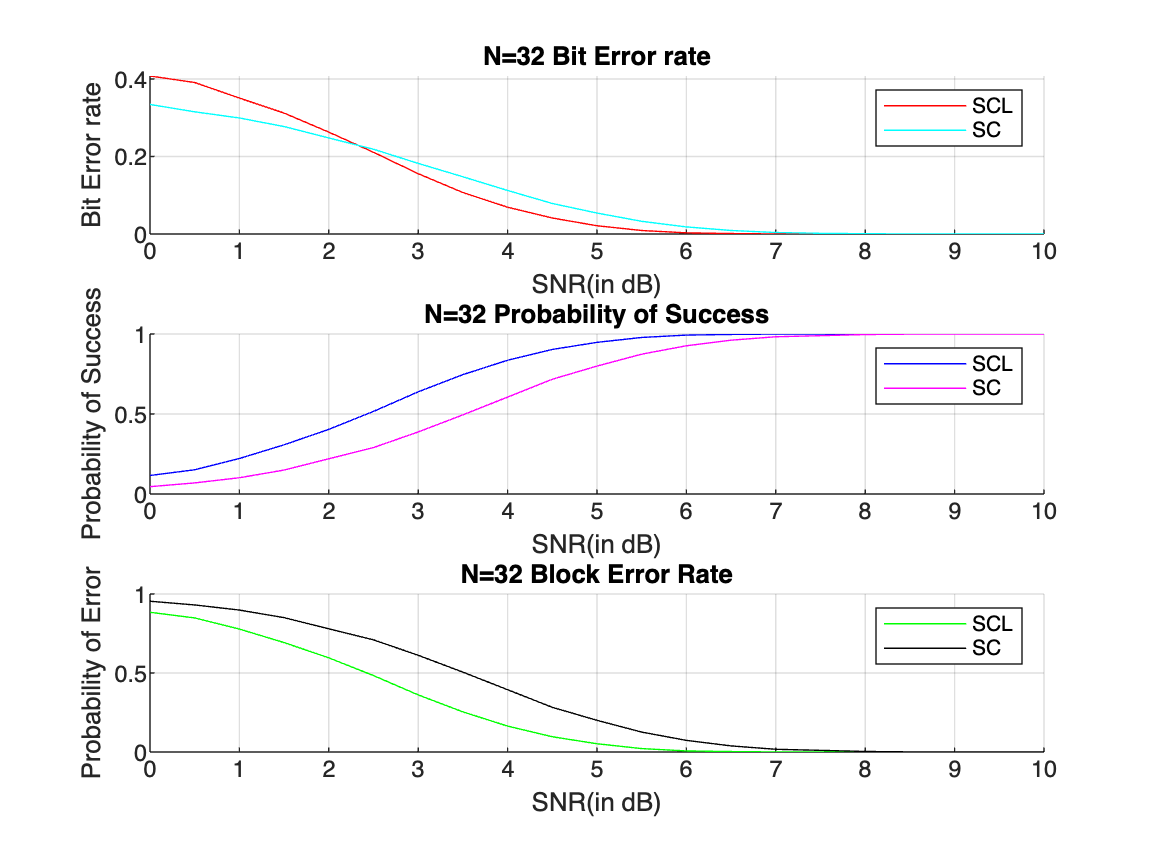

%Eb/No (SNR)
SNR=0:0.5:10;
crcg = flip([1 1 1 0 0 0 1 0 0 0 0 1],2);
prob=zeros(1,length(SNR));
prob_1=zeros(1,length(SNR));
ber=zeros(1,length(SNR));
ber_1=zeros(1,length(SNR));
nsim=10000;

for x=1:length(SNR)
  for y = 1:nsim
    N = 32; A = 16; crc_Length = 11; number_of_List = 4; 
    n = log2(N);
    EbNodB = SNR(x);
    K = A + crc_Length; 
    %Reliability sequence for N bits
    K_1=27;
    Q1 = reliability_seq(reliability_seq<=N); 
    %Frozen positions for SCL First N-K bits of Q1
    Frozen_bit = Q1(1:N-K);
    %Frozen positions for SC First N-K_1 bits of Q1
    Frozen_bit_1 = Q1(1:N-K_1);
    %Generate Random A-bits message for SCL
    msg = randi([0 1],1,A);
    %Generate Random K_1-bits message for SC
    msg_1 = randi([0 1],1,K_1);
    u = zeros(1,N);
    % N bit message for SC
    u(Q1(N-K_1+1:end)) = msg_1;
    K_bit_msg = zeros(1,N);
    % K bit message for SC
    K_bit_msg(Q1(N-K+1:end)) = crc(crc_Length,msg); 
    %Encoded messages
    encoded_message=encoding(K_bit_msg,1:N);
    encoded_message_1=encoding(u,1:N);
    %modulated messages
    modulated = bpsk(encoded_message);
    modulated_1 = bpsk(encoded_message_1);
    %added gaussian white noise in it
    recieved = awgn(modulated,EbNodB);
    recieved_1 = awgn(modulated_1,EbNodB);
    %decoded message using SCL method
    N_bit_decoded_message=scl_decode_recursive(number_of_List,recieved,n,N,Frozen_bit);
    K_bit_decoded_message = squeeze(N_bit_decoded_message(:,n+1,Q1(N-K+1:end))); 
    %taking out A bit from decoded message using crc checker
    A_bit_decoded_message=crc_checker(K_bit_decoded_message,number_of_List,A);
    %SC decoding 
    [A_bit_decoded_message_by_SC,A_bit_decoded_message_by_SC_1] = SC_Decode(1:N,Frozen_bit_1,recieved_1);
    %Calculation of probabilty,BLER and BER in SCL
    if(any(msg~=A_bit_decoded_message))
            c=xor(msg,A_bit_decoded_message);
            ber(x)=sum(c)+ber(x);
    else
        prob(x)=prob(x)+1;
    end
     %Calculation of probabilty,BLER and BER in SCL
    if(any(msg_1~=A_bit_decoded_message_by_SC(Q1(N-K_1+1:end))))
            c=xor(msg_1,A_bit_decoded_message_by_SC(Q1(N-K_1+1:end)));
            ber_1(x)=sum(c)+ber_1(x);
    else
        prob_1(x)=prob_1(x)+1;
    end
  end
end
%final calculation of probability,BLER,BER
ber=ber./(length(A_bit_decoded_message)*nsim);
prob=prob./nsim;
ber_1=ber_1./(length(A_bit_decoded_message_by_SC)*nsim);
prob_1=prob_1./nsim;

%drawing figures
figure;
subplot(3,1,1);
hold on;
grid on;
%Plot of Bit error rate of SC and SCL
title('N=32 Bit Error rate');
plot(SNR,ber,'r');
plot(SNR,ber_1,'c');
xlabel('SNR(in dB)');
ylabel('Bit Error rate');
legend('SCL','SC');
hold off;

subplot(3,1,2);
%Plot of Probability of success of SC and SCL
title('N=32 Probability of Success');
hold on;
grid on;
plot(SNR,prob,'b');
plot(SNR,prob_1,'m');
xlabel('SNR(in dB)');
ylabel('Probability of Success');
legend('SCL','SC');
hold off;

subplot(3,1,3);
%Plot of Probability of error(BLER) of SC and SCL
title('N=32 Block Error Rate');
hold on;
grid on;
plot(SNR,1-prob,'g');
plot(SNR,1-prob_1,'k');
xlabel('SNR(in dB)');
ylabel('Probability of Error');
legend('SCL','SC');
hold off;